# Image Datastores

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

pathToImages = "../data/TestImages";

## Task 1

You can create an image datastore with the `imageDatastore` function.

`imageDatastore``(``location``)`

imds = imageDatastore(pathToImages)

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\TestImages\1.jpg';
                              ' ...\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\TestImages\2.jpg';
                              ' ...\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\TestImages\3.jpg'
                               ... and 3 more
                              }
                     Folders: {
                              ' ...\luisa\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\TestImages'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


## Task 2

The `montage` function can be used to display images in a datastore.

`montage``(``datastore``)`

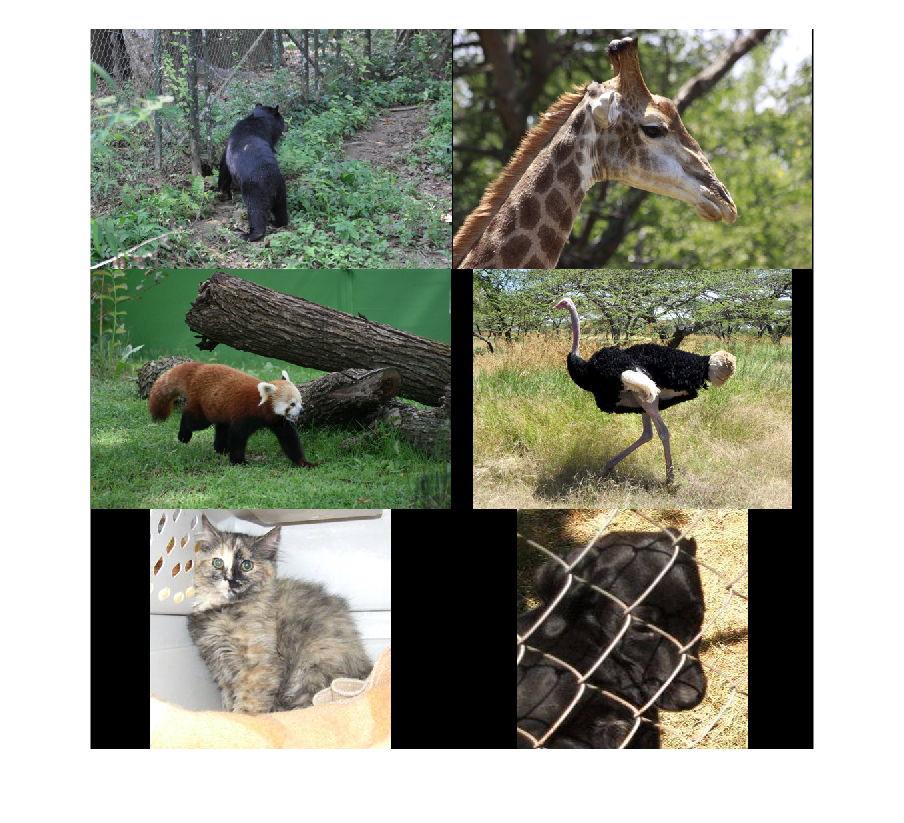

montage(imds)

## Task 3

net = googlenet

net =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


## Task 4

An augmented image datastore can perform simple preprocessing on an entire collection of images. To create this datastore, use the `augmentedImageDatastore` function using your network's image input size as input.

`auds` `=` `augmentedImageDatastore``([``r` `c``]``,``imds``)`

auds = augmentedImageDatastore([224 224], imds)

auds =   augmentedImageDatastore with properties:

             NumObservations: 6
                       Files: {6×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [224 224]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


## Task 5

The `classify` function will use a network to predict labels for an image. You can also use a datastore as input to classify many images at once.

`label` `=` `classify``(``net``,``ds``)`

predictedLabels = classify(net, auds)

predictedLabels = 6×1 categorical array
     American black bear 
     impala 
     lesser panda 
     ostrich 
     tabby 
     gorilla 
